# Code 5: Increasing trend of saturation limit from literature

By Nithin Sivadas

27 Dec 2025

This code plots the trend of increasing saturation limit observed from literature pertaining to polar cap potential saturation observations. Extended Data Table 2: Observational studies on polar cap potential saturation

% Specify the output folder where you'd like to store the images
outputFolder = 'results/';
setExportFig = 0;

Generating table

sz = [9 4]; % 5 rows, 3 variables
varTypes = {'string', 'datetime', 'double', 'string' };
varNames = {'Study', 'Year', 'SaturationLimit', 'Instruments'};
T = table('Size', sz, 'VariableTypes', varTypes, 'VariableNames', varNames);

T.Study={"Reiff et al., 1981",...
    "Wygant et al., 1983",...
    "Weimer et al., 1990",...
    "Boyle et al., 1997",...
    "Russell et al., 2001",...
    "Liemohn and Ridley, 2002",...
    "Shepherd et al., 2002",...
    "Nagatsuma, 2002",...
    "Hairston et al., 2005"}';

Years = [1981;1983;1990;1997;2001;2002;2002;2002;2005];
T.Year = datetime(Years,1,1,'Format','yyyy');
T.SaturationLimit = [3,0.5,4,8,3,10,3,5,10]';
T.Instruments={"LEO satellites: AE-C,AE-D,S3-3",...
    "LEO satellites S3-3",...
    "Magnetometers AE-Index",...
    "DMSP satellites",...
    "AMIE",...
    "AMIE",...
    "SuperDARN radars",...
    "Magnetometers PC-Index",...
    "DMSP Satellites"}';

Plotting the trend of the polar cap saturation limit

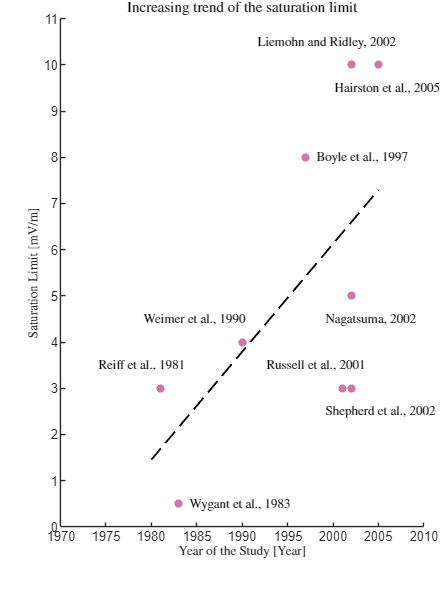

f1=figure;
resize_figure(f1,120,90);
scatter(year(T.Year),T.SaturationLimit, 'filled',...
    'SizeData', 20, ...
    'MarkerFaceColor', '#cc79a7');
hold on;
h = lsline;                % Create the trend line and capture its handle
h.Color = 'k';             % Change color to red
h.LineWidth = 1;           % Increase thickness to 2 points
h.LineStyle = '--';        % Change to a dashed line
hold on;
vOffset = zeros(size(T.SaturationLimit));
vOffset(1) = 0.5;  % Shift 1st 2002 point up
vOffset(3) = 0.5; % Shift 2nd 2002 point down
vOffset(5) = 0.5;
vOffset(6) = 0.5;
vOffset(7) = -0.5;
vOffset(8) = -0.5;
vOffset(9) = -0.5;

hOffset = zeros(size(T.SaturationLimit));
hOffset(1) = -8;
hOffset(3) = -12;
hOffset(5) = -9.5;
hOffset(6) = -11.5;
hOffset(7) = -4;
hOffset(8) = -4;
hOffset(9) = -6;
text(year(T.Year) + 1 +hOffset, T.SaturationLimit + vOffset, T.Study, ...
    'VerticalAlignment', 'middle', ...
    'FontSize', 7);
xlabel('Year of the Study [Year]','FontSize',7);
ylabel('Saturation Limit [mV/m]','FontSize',7);
xlim([1970,2010]);
ylim([0,11]);
fontname('Helvetica');
fontsize(7, "points")
title('Increasing trend of the saturation limit','FontSize',8);

if setExportFig
    %exportgraphics(f1,[outputFolder,'ExtendedDataFig9.pdf'],'ContentType','vector');
    exportgraphics(f1,[outputFolder,'ExtendedDataFigure10.png'],'Resolution',600);
end

## Functions

function resize_figure( figureHandle, vert, horz )

## resize_figure.m Resizes figure into a standard paper size

%--------------------------------------------------------------------------
% Input
%------
% figureHandle
% vert - Vertical page size in mm (Default Letter Size)
% horz - Horizontal page size in mm (Default Letter Size)

if nargin<3 || isempty(horz)
    horz = 215.9;
end
if nargin<2 || isempty(vert)
    vert = 279.4;
end

% Centimeter Units
X = horz/10;
Y = vert/10;
xMargin = 0;
yMargin = 0;
xSize = X - 2*xMargin;
ySize = Y - 2*yMargin;

% Figure size displayed on screen
movegui(figureHandle, 'center');
set(figureHandle,'color','w');
set(figureHandle, 'Units', 'centimeters', 'Position', [0 0 xSize ySize])
end